clc; close; clear all;

%%
syms iL1 vc L1on L1off L2 RL1 RL2 C Rc Ro vd N1 N2 d s R1 R2 C1 C2


%% ON

iL1_d = vd/L1on - (RL1/L1on)*iL1

$$iL1\_d = \frac{\mathrm{vd}}{\mathrm{L1on}}-\frac{{\mathrm{RL}}_{1}\,{\mathrm{iL}}_{1}}{\mathrm{L1on}}$$

vc_d = -(1/(C*(Rc+Ro))) * vc

$$vc\_d = -\frac{\mathrm{vc}}{C\,\left(\mathrm{Rc}+\mathrm{Ro}\right)}$$


vo = (Ro/(Ro+Rc))*vc

$$vo = \frac{\mathrm{Ro}\,\mathrm{vc}}{\mathrm{Rc}+\mathrm{Ro}}$$


% Vectores
x = [iL1; vc];
f = [iL1_d; vc_d];
h = vo;

%% State space 

%Linealizacion del sistema (Jacobiano)
Aon = jacobian(f, x)  %df/dx

$$Aon = \left(\begin{array}{cc} -\frac{{\mathrm{RL}}_{1}}{\mathrm{L1on}} & 0\\ 0 & -\frac{1}{C\,\left(\mathrm{Rc}+\mathrm{Ro}\right)} \end{array}\right)$$

Bon = jacobian(f, vd)  %df/du

$$Bon = \left(\begin{array}{c} \frac{1}{\mathrm{L1on}}\\ 0 \end{array}\right)$$

Con = jacobian(h, x)  %dh/dx

$$Con = \left(\begin{array}{cc} 0 & \frac{\mathrm{Ro}}{\mathrm{Rc}+\mathrm{Ro}} \end{array}\right)$$

Don = jacobian(h, vd)  %dh/du

$$Don = 0$$


% Puntos de equlibrio REEMPLAZAR POR VALORES POSTA
% x1_eq = 0;
% x2_eq = 0;
% x3_eq = 0;
% x4_eq = 0;
% u_eq = 0;

% Xeq = [x1_eq x2_eq x3_eq x4_eq];
% delta_xeq = [0 0 0 0];
% Ueq = [u_eq];

%Calculo mmatrices en pto de equlibrio
% A = subs(A, {'x1','x2','x3', 'x4', 'u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
% B = subs(B, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
% C = subs(C, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});
% D = subs(D, {'x1','x2','x3', 'x4','u'}, {x1_eq, x2_eq, x3_eq, x4_eq, u_eq});

% Gss : Sistema linealizado en espacio de estados
% A = double(A);
% B = double(B);
% C = double(C);
% D = double(D);


%% OFF

n = N1/N2;

vc_d = -(Ro/(C*(Ro-Rc)))*(n*iL1 + vc/Ro)

$$vc\_d = \frac{\mathrm{Ro}\,\left(\frac{\mathrm{vc}}{\mathrm{Ro}}+\frac{N_{1}\,{\mathrm{iL}}_{1}}{N_{2}}\right)}{C\,\left(\mathrm{Rc}-\mathrm{Ro}\right)}$$


% vo = Ro*(-n*iL1+C*vc_d); 

vo = vc - Rc * C * vc_d

$$vo = \mathrm{vc}-\frac{\mathrm{Rc}\,\mathrm{Ro}\,\left(\frac{\mathrm{vc}}{\mathrm{Ro}}+\frac{N_{1}\,{\mathrm{iL}}_{1}}{N_{2}}\right)}{\mathrm{Rc}-\mathrm{Ro}}$$


iL1_d = (1/(n*L2))*(-n*iL1*RL2 + vo)

$$iL1\_d = -\frac{N_{2}\,\left(\frac{N_{1}\,{\mathrm{RL}}_{2}\,{\mathrm{iL}}_{1}}{N_{2}}-\mathrm{vc}+\frac{\mathrm{Rc}\,\mathrm{Ro}\,\left(\frac{\mathrm{vc}}{\mathrm{Ro}}+\frac{N_{1}\,{\mathrm{iL}}_{1}}{N_{2}}\right)}{\mathrm{Rc}-\mathrm{Ro}}\right)}{L_{2}\,N_{1}}$$


%iL1_d = -n/L1*(1-(Rc*Ro)/(Ro*(Rc+Ro))) * vc + n*n/L1 * (RL2 + (Rc*Ro)/(Rc+Ro)) *iL1;

%  iL1_d = n/L1*(-n*(Ro+RL2)*iL1 + Ro*((vc + n * iL1*Ro)/(Rc+Ro)));
%  vc_d = -(1/(C*(Ro+Rc)))*(vc + n*Ro*iL1);
%  
%  vo = vc - Rc * C * vc_d;

% Vectores
x = [iL1; vc];
f = [iL1_d; vc_d];
h = vo;

%% State space 

%Linealizacion del sistema (Jacobiano)
Aoff = jacobian(f, x)  %df/dx

$$Aoff = \left(\begin{array}{cc} -\frac{N_{2}\,\left(\frac{N_{1}\,{\mathrm{RL}}_{2}}{N_{2}}+\frac{N_{1}\,\mathrm{Rc}\,\mathrm{Ro}}{N_{2}\,\left(\mathrm{Rc}-\mathrm{Ro}\right)}\right)}{L_{2}\,N_{1}} & -\frac{N_{2}\,\left(\frac{\mathrm{Rc}}{\mathrm{Rc}-\mathrm{Ro}}-1\right)}{L_{2}\,N_{1}}\\ \frac{N_{1}\,\mathrm{Ro}}{C\,N_{2}\,\left(\mathrm{Rc}-\mathrm{Ro}\right)} & \frac{1}{C\,\left(\mathrm{Rc}-\mathrm{Ro}\right)} \end{array}\right)$$

Boff = jacobian(f, vd)  %df/du

$$Boff = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Coff = jacobian(h, x)  %dh/dx

$$Coff = \left(\begin{array}{cc} -\frac{N_{1}\,\mathrm{Rc}\,\mathrm{Ro}}{N_{2}\,\left(\mathrm{Rc}-\mathrm{Ro}\right)} & 1-\frac{\mathrm{Rc}}{\mathrm{Rc}-\mathrm{Ro}} \end{array}\right)$$

Doff = jacobian(h, vd)  %dh/du

$$Doff = 0$$


%% Promedios 

A_a = Aon*d+Aoff*(1-d);
B_a = Bon*d+Boff*(1-d);
C_a = Con*d+Coff*(1-d);
D_a = Don*d+Doff*(1-d);


%% Funcion transferencia

Phi=inv(s*eye(2)-A_a);

H=C_a*Phi*B_a;

X = Phi * B_a * vd; % los estados considerando D de flyback

X = subs(X, s, 0);

%% Transferencia vo respecto a d

H_d = C_a * Phi * ((Aon - Aoff) * X + (Bon - Boff)*vd) + (Con-Coff)*X;



%% ceros y polos

[N, D] = numden(H_d)


%%

%% Reemplazo valores

Ro_eq = 100;
L1on_eq = 11e-3;
L1off_eq = 10e-3;
L2_eq = 16e-6;
L3_eq = 100e-6;
C_eq = 1e-6;
RL1_eq = 80e-3;
RL2_eq = 1e-3;
RL3_eq = 1e-3; 
Rc_eq = 0.5;
d_eq = 0.35;
vd_eq = 300;
N1_eq = 50;
N2_eq = 2;
N3_eq = 5;

Hd_values = subs(H_d, {'L1on', 'L1off', 'L2', 'RL1', 'RL2', 'C', 'Rc', 'Ro', 'vd', 'N1', 'N2', 'd'}, {L1on_eq L1off_eq L3_eq RL1_eq RL3_eq C_eq Rc_eq Ro_eq vd_eq N1_eq N3_eq d_eq});

%%
[N, D] = numden(Hd_values)

$$N = 554386140000000\,s^{2}+5952452805012030000000\,s-4480495612303218000000000000$$

$$D = 16396892832790866\,s^{2}+110809614386528999197\,s+69439963320992433681800000$$

[N_coeffs, a] = coeffs(N, s)

$$N\_coeffs = \left(\begin{array}{ccc} 554386140000000 & 5952452805012030000000 & -4480495612303218000000000000 \end{array}\right)$$

$$a = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$

[D_coeffs, b] = coeffs(D, s)

$$D\_coeffs = \left(\begin{array}{ccc} 16396892832790866 & 110809614386528999197 & 69439963320992433681800000 \end{array}\right)$$

$$b = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$


%%


%%
sys = tf(double(N_coeffs), double(D_coeffs))

sys =
 
  5.544e14 s^2 + 5.952e21 s - 4.48e27
  -----------------------------------
  1.64e16 s^2 + 1.108e20 s + 6.944e25
 
Continuous-time transfer function.



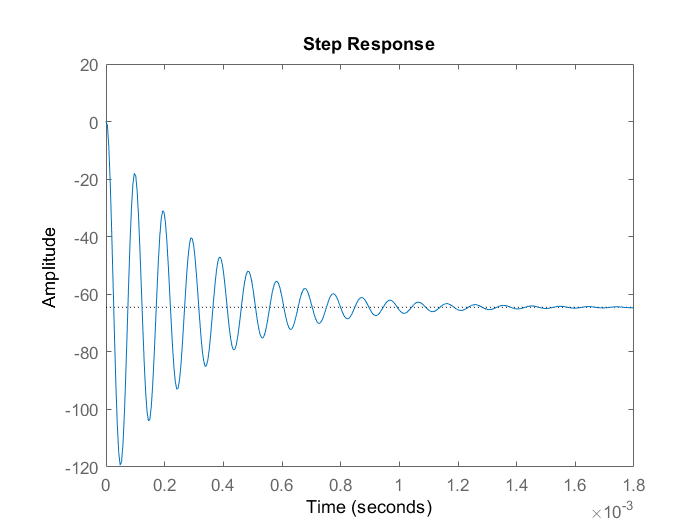

step(sys)

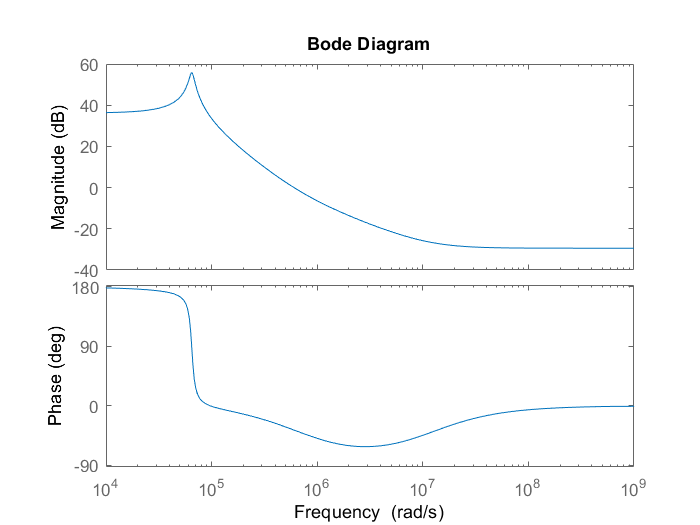

figure('Name', 'Bode'); bode(sys)

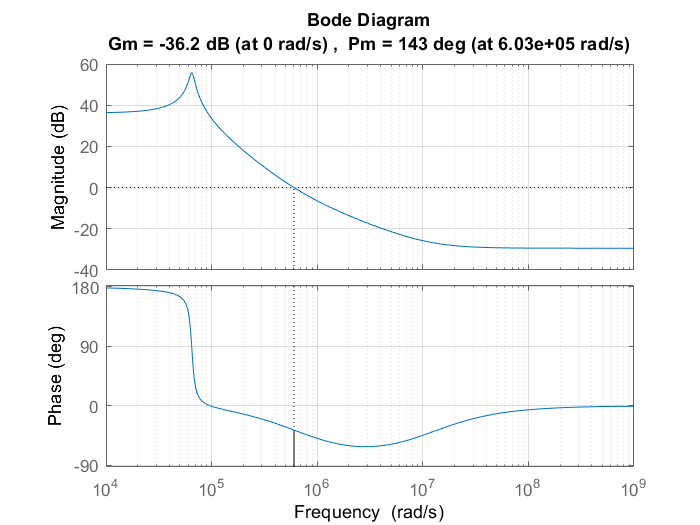

margin(sys)
grid on


step(sys)

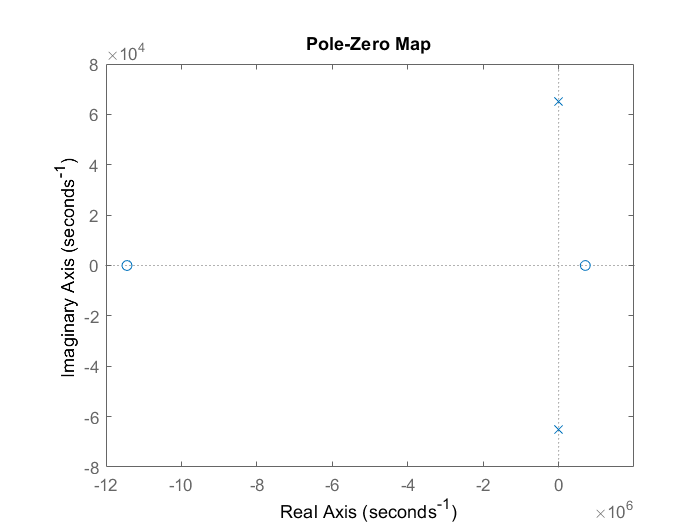

pzplot(sys)

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   2
=> Number of poles in RHP of closed-loop system:   2
=> Closed-loop-system is unstable


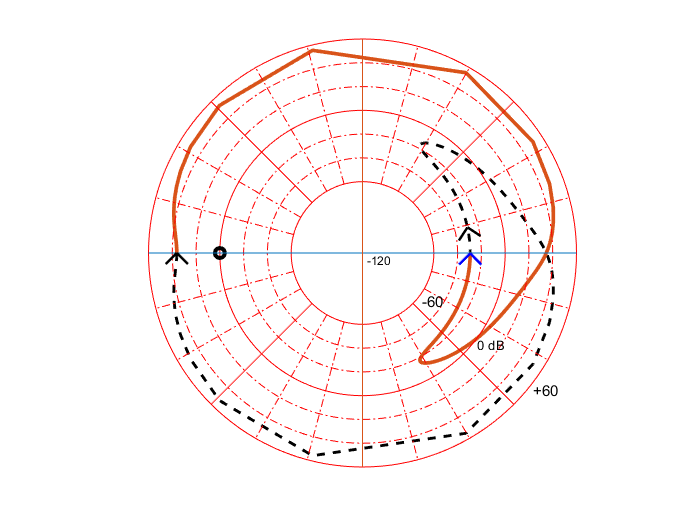


nyqlog(sys)

sys = zpk(sys)

sys =
 
  0.03381 (s+1.144e07) (s-7.063e05)
  ---------------------------------
      (s^2 + 6758s + 4.235e09)
 
Continuous-time zero/pole/gain model.



## Control PI

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Gc = 1/(s*(s+5000));
L = Gc*sys

L =
 
   0.03381 (s+1.144e07) (s-7.063e05)
  -----------------------------------
  s (s+5000) (s^2 + 6758s + 4.235e09)
 
Continuous-time zero/pole/gain model.



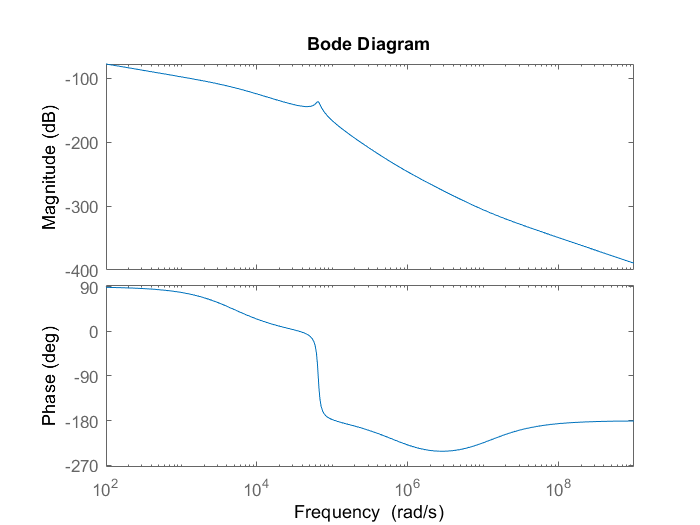

figure('Name', 'Bode2'); bode(L)

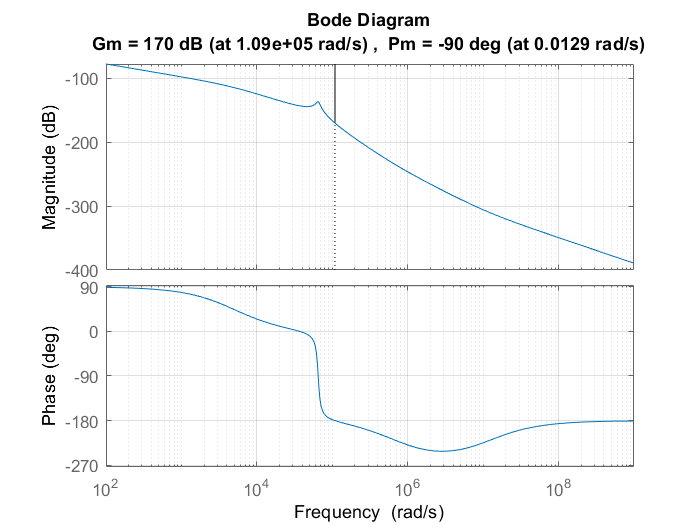

margin(L)
grid on

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   1
=> Number of poles in RHP of closed-loop system:   1
=> Closed-loop-system is unstable


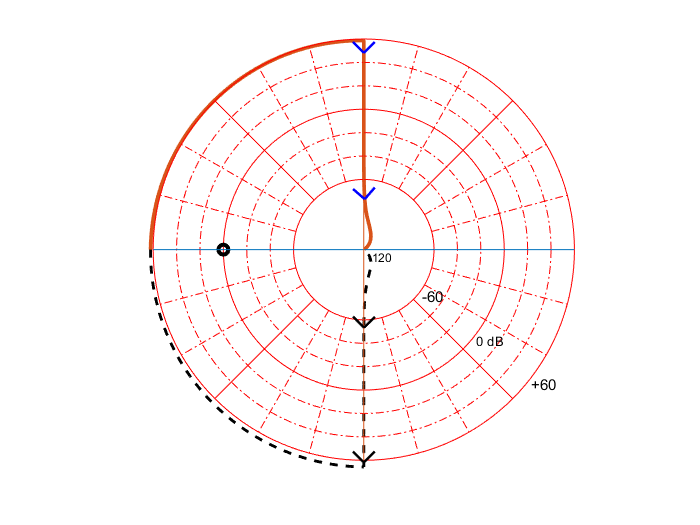

nyqlog(L)